clear
clc

xi = linspace(-6,2,300);
yi = linspace(-4,4,300);
[X,Y] = meshgrid(xi,yi);
X

X =    -6.0000   -5.9732   -5.9465   -5.9197   -5.8930   -5.8662   -5.8395   -5.8127   -5.7860   -5.7592   -5.7324   -5.7057   -5.6789   -5.6522   -5.6254   -5.5987   -5.5719   -5.5452   -5.5184   -5.4916   -5.4649   -5.4381   -5.4114   -5.3846   -5.3579   -5.3311   -5.3043   -5.2776   -5.2508   -5.2241   -5.1973   -5.1706   -5.1438   -5.1171   -5.0903   -5.0635   -5.0368   -5.0100   -4.9833   -4.9565   -4.9298   -4.9030   -4.8763   -4.8495   -4.8227   -4.7960   -4.7692   -4.7425   -4.7157   -4.6890
   -6.0000   -5.9732   -5.9465   -5.9197   -5.8930   -5.8662   -5.8395   -5.8127   -5.7860   -5.7592   -5.7324   -5.7057   -5.6789   -5.6522   -5.6254   -5.5987   -5.5719   -5.5452   -5.5184   -5.4916   -5.4649   -5.4381   -5.4114   -5.3846   -5.3579   -5.3311   -5.3043   -5.2776   -5.2508   -5.2241   -5.1973   -5.1706   -5.1438   -5.1171   -5.0903   -5.0635   -5.0368   -5.0100   -4.9833   -4.9565   -4.9298   -4.9030   -4.8763   -4.8495   -4.8227   -4.7960   -4.7692   -4.7425   -4.7157   -4

Y

Y =    -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000
   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3.9732   -3

Z = ps_example([X(:),Y(:)]);

Z = reshape(Z,size(X));
Z

Z =     5.0000    4.9472    4.8958    4.8459    4.7974    4.7503    4.7047    4.6605    4.6177    4.5764    4.5365    4.4980    4.4609    4.4253    4.3911    4.3584    4.3271    4.2972    4.2687    4.2417    4.2161    4.1920    4.1692    4.1479    4.1281    4.1096    4.0926    4.0771    4.0629    4.0502    4.0389    4.0291    4.0207    4.0137    4.0082    4.0040    4.0014    4.0001    2.0729    2.0593    2.0471    2.0362    2.0268    2.0188    2.0122    2.0070    2.0032    2.0009    2.0000    2.0005
    4.9732    4.9204    4.8691    4.8192    4.7707    4.7236    4.6779    4.6337    4.5910    4.5496    4.5097    4.4712    4.4342    4.3986    4.3644    4.3316    4.3003    4.2704    4.2420    4.2150    4.1894    4.1652    4.1425    4.1212    4.1013    4.0829    4.0659    4.0503    4.0362    4.0235    4.0122    4.0023    3.9939    3.9869    3.9814    3.9773    3.9746    3.9733    2.0462    2.0325    2.0203    2.0095    2.0000    1.9920    1.9854    1.9802    1.9765    1.9741    1.9733    1

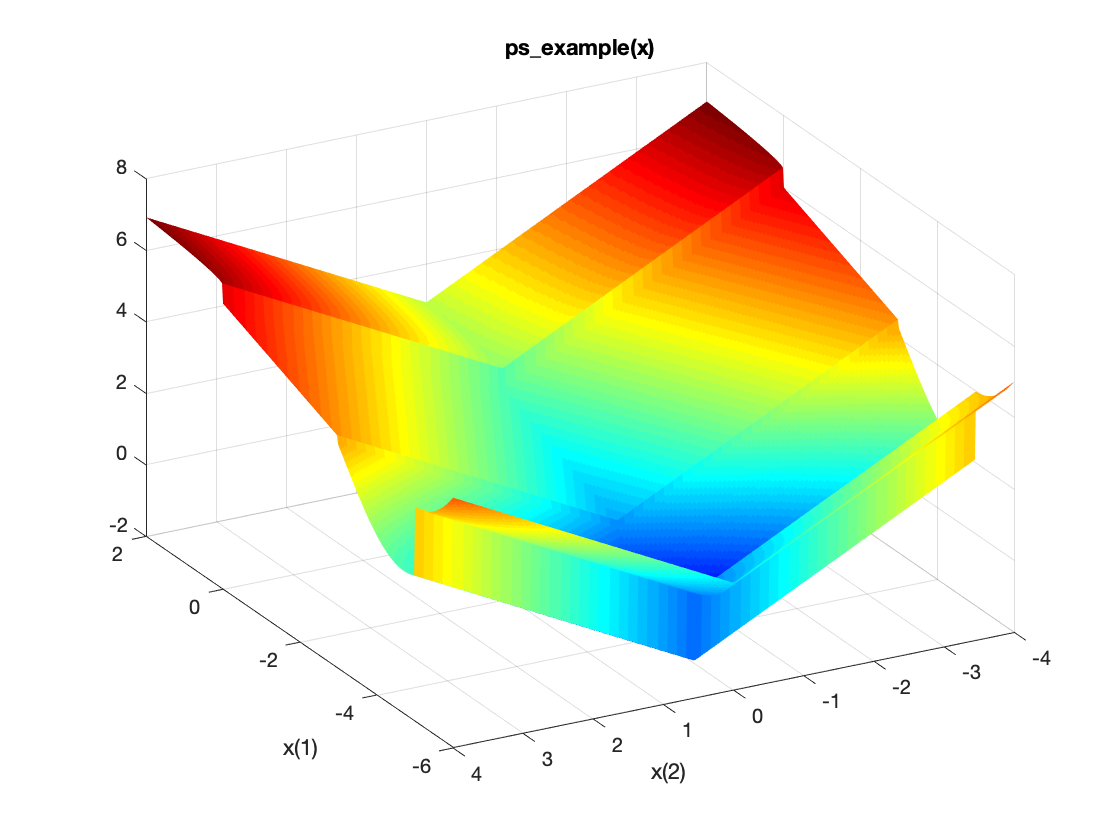

surf(X,Y,Z,'MeshStyle','none')
colormap 'jet'
xlabel('x(1)')
ylabel('x(2)')
title('ps\_example(x)')

rng default % For reproducibility
x = ga(@ps_example,2)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =    -4.6793   -0.0860
